# Análisis de tendencia de la Cuenca del Río Pánuco

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1098 archivos
>>>>> Obteniendo la zona de estudio
D:\DATA\MOD13A2\061\*.hdf
>>>>> Analizando 1098 archivos
>>>>> Obteniendo latitud y longitud
>>> Cargando área de estudio
>>> Área de estudio existente 1


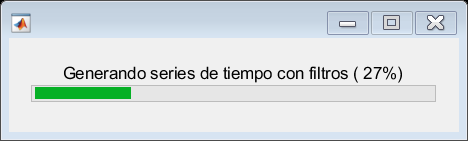

import matlab.io.hdfeos.*;
clearvars -except study_area;

%directorio de datos
dir_data = "D:\DATA\";
modis_product = 'MOD13A2';
kml_file = "RH26";
% umbral para ajuste de ventana y datos 
umbral_mapa=0.1;
umbral_datos = 0.09;
% Cargar los datos en los arreglos
anio_inicio = 2000;
m_cargar_datos

## Procesar la información

% Declaraciones
% Los años que se desean consultar
meses = [4,9];
anios = 2000:2022;

% Arreglo donde se almacenara el promedio de NDVI por año
tabla_tendencia =zeros(length(anios),6);


## Filtrar

arr_ndvi_mj(arr_ndvi_mj<=0)=nan; 
bp=waitbar(0,'Filtrando información'); 
 
for y= 1:length(anios)
        % Abril 
        tmp =  find(  info_hdf.anio == anios(y) & info_hdf.mes == 4  ); % Abril
        if( ~isempty (tmp))
            % promedio
            tabla_tendencia(y,2) = mean(arr_ndvi_mj (:,:,tmp),"all","omitnan");
            % maximo
            tabla_tendencia(y,1) = max(arr_ndvi_mj (:,:,tmp),[],"all","omitnan");
            % minimo
            tabla_tendencia(y,3) = min(arr_ndvi_mj (:,:,tmp),[],"all","omitnan");
        end
   
        % Septiembre 
        tmp =  find(  info_hdf.anio == anios(y) & info_hdf.mes == 9  ); 
        if( ~isempty (tmp))
            % promedio
            tabla_tendencia(y,5) = mean(arr_ndvi_mj (:,:,tmp),"all","omitnan");
            % maximo
            tabla_tendencia(y,4) = max(arr_ndvi_mj (:,:,tmp),[],"all","omitnan");
            % minimo
            tabla_tendencia(y,6) = min(arr_ndvi_mj (:,:,tmp),[],"all","omitnan");
        end
                 
    waitbar(y/length(anios),bp,sprintf('Filtrando información: Año: (%4d) ',anios(y)));
end
close(bp); 


### Resultados 

#### Regresion lineal en mes de abril

% % anios = 1:length(anios);
tam_letra=10;

[a0,a1,ajuste] = f_reglin(1:length(anios),tabla_tendencia(:,2)');
disp("abril_promedio y="+a0+"+"+a1+"x");

abril_promedio y=0.4303+0.0012323x



figure;
plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,2),LineWidth=2);
%title('NDVI promedio x estación');
xlabel('Años');
xticks(1:length(anios));
xticklabels(anios);
ylabel('NDVI');
%xlim([0 (length(linea_tiempo_promedio)+1)]);
ylim([0 1]);
xtickangle(45);
ax = gca;
ax.FontSize=tam_letra; 

hold on
[a0,a1,ajuste] = f_reglin(1:length(anios),tabla_tendencia(:,1)');
disp("abril_max y="+a0+"+"+a1+"x");

abril_max y=0.92249+0.0012734x


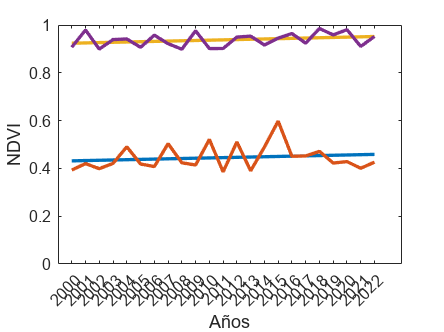


plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,1),LineWidth=2);

% [~,~,ajuste] = m_reglin(anios,tabla_tendencia(:,3)');
% plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,3),LineWidth=2);
hold off
exportgraphics(gca,"img/at_tendencia_promedio_año_abril.png",'Resolution',300);

#### Mes de septiembre


[a0,a1,ajuste] = f_reglin(1:length(anios),tabla_tendencia(:,5)');
disp("sept_prom y="+a0+"+"+a1+"x");

sept_prom y=0.65474+0.0008817x



figure;
plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,5),LineWidth=2);
%title('NDVI promedio x estación');
xlabel('Años');
xticks(1:length(anios));
xticklabels(anios);
ylabel('NDVI');
%xlim([0 (length(linea_tiempo_promedio)+1)]);
ylim([0 1]);
xtickangle(45);
ax = gca;
ax.FontSize=tam_letra; 

hold on
[a0,a1,ajuste] = f_reglin(1:length(anios),tabla_tendencia(:,4)');
disp("sept_max y="+a0+"+"+a1+"x");

sept_max y=0.9493+0.0007916x


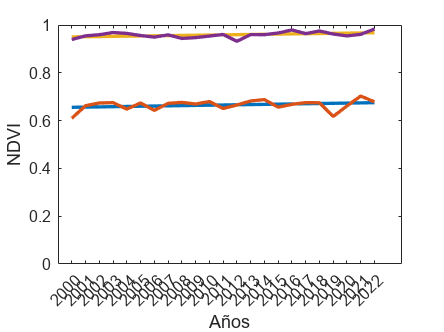


plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,4),LineWidth=2);

% [~,~,ajuste] = m_reglin(anios,tabla_tendencia(:,6)');
% plot(1:length(anios),ajuste,1:length(anios),tabla_tendencia(:,6),LineWidth=2);
hold off

exportgraphics(gca,"img/at_tendencia_promedio_año_septiembre.png",'Resolution',300);